#  E10 - Local Features

## HoG

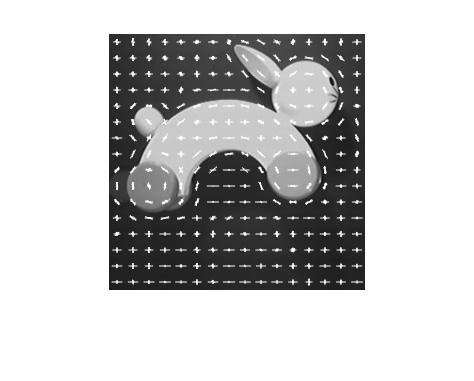

close all
I = imread('rabbit.jpg');
im = imresize(I, [256 256]);
imshow(im);

[HoG, HoGVec] = extractHOGFeatures(im, 'CellSize', [16 16], 'BlockSize', [3 3], 'NumBins', 9);

hold on
plot (HoGVec);

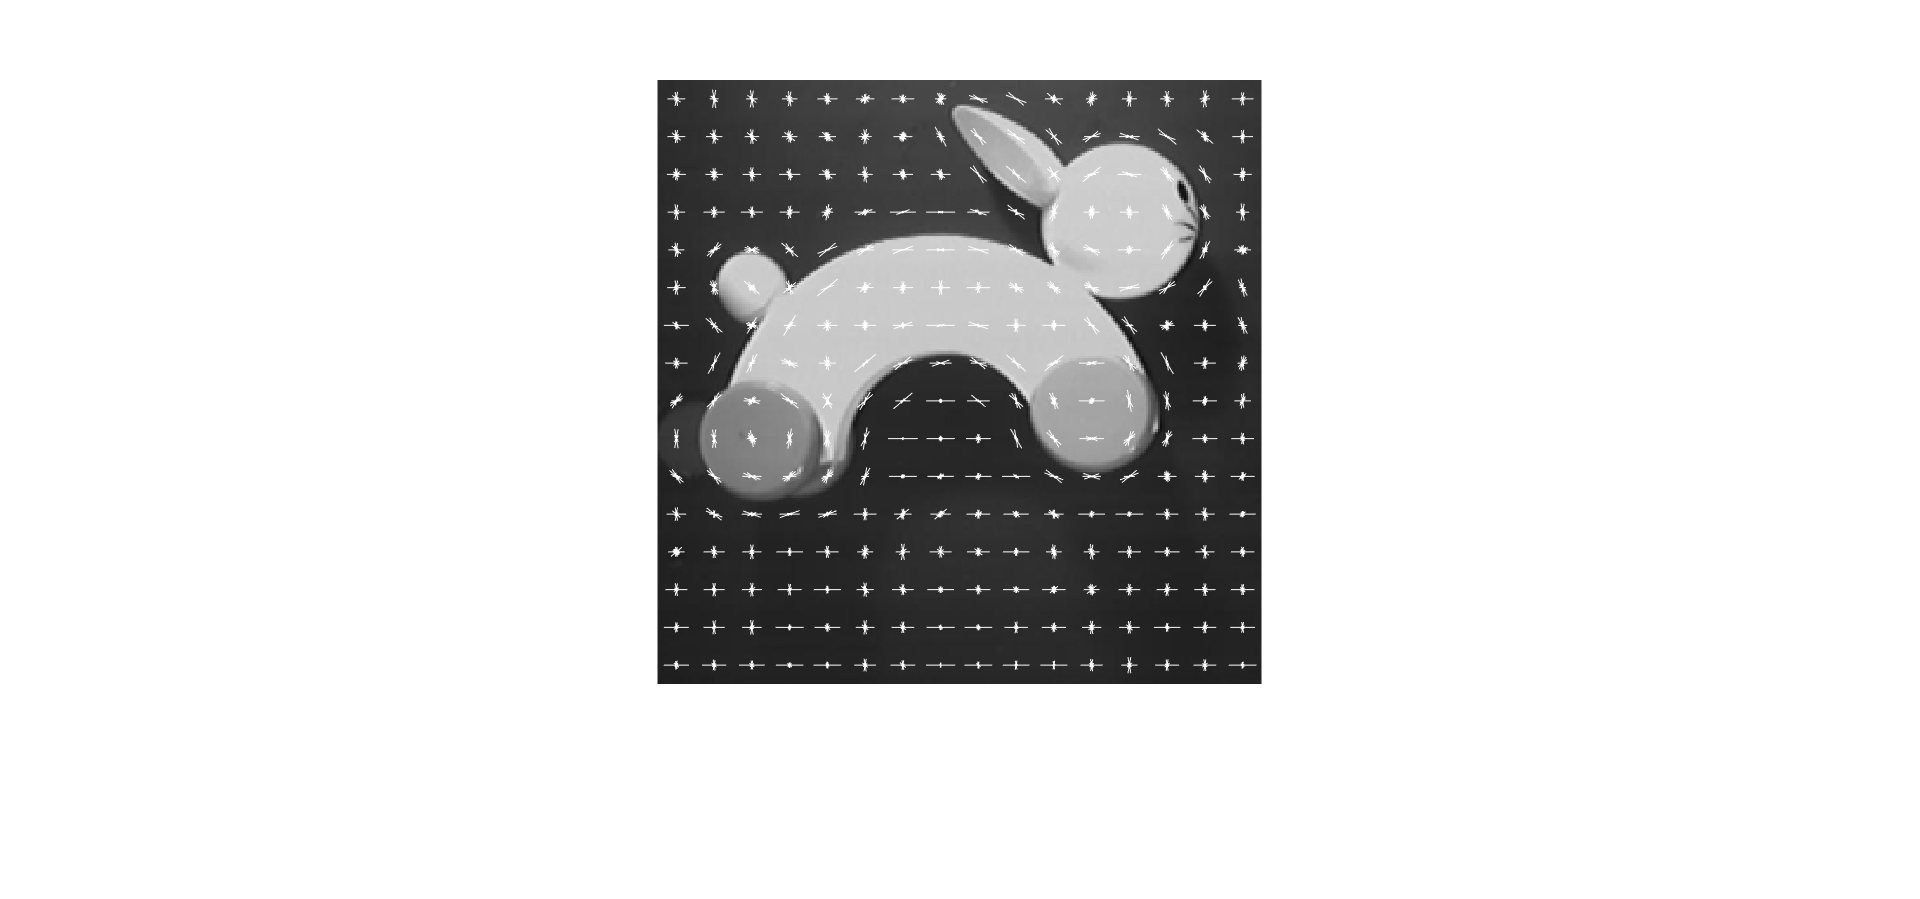

% busquem un retall per HoG
[c, f] = getpts;

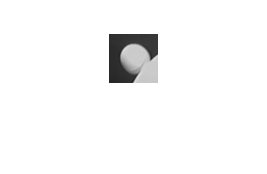

rect = [c-24, f-24, 48, 48];
Retall = imcrop(im, rect);
figure
imshow(Retall);

HoGR = extractHOGFeatures(Retall, 'CellSize', [16 16], 'BlockSize', [3 3], 'NumBins', 9);
FIG = reshape(HoG, [81,14*14])';

Semblanca = zeros([14*14,1]);
for i = 1:14*14
    Semblanca(i) = sum(min(FIG(i,:), HoGR)); % similitut per intersecció de l'histograma
end

[val, pos_block] = max(Semblanca);

% Ex: dibuixar un rectangle en la possició pos_block

## Diferenciar histogrames de color

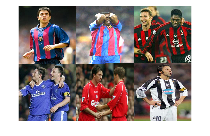

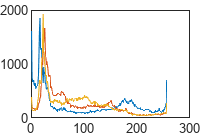

close all
im = imresize(imread('team1.jpg'), [256 256]);
im1 = imresize(imread('team2.jpg'), [256 256]);
im2 = imresize(imread('team5.jpg'), [256 256]);
im3 = imresize(imread('team11.jpg'), [256 256]);
im4 = imresize(imread('team12.jpg'), [256 256]);
im5 = imresize(imread('team8.jpg'), [256 256]);

montage({im, im1, im2, im3, im4, im5});

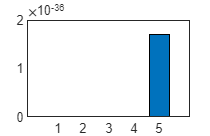


h = Calcular_Histogrames_rg(im);
h1 = Calcular_Histogrames_rg(im1);
h2= Calcular_Histogrames_rg(im2);
h3 = Calcular_Histogrames_rg(im3);
h4 = Calcular_Histogrames_rg(im4);
h5 = Calcular_Histogrames_rg(im5);

S = zeros(5,1);

S(1) = Calcular_Similitut(h, h1);
S(2) = Calcular_Similitut(h, h2);
S(3) = Calcular_Similitut(h, h3);
S(4) = Calcular_Similitut(h, h4);
S(5) = Calcular_Similitut(h, h5);

bar(S),

function [h] = Calcular_Histogrames_rg(im)
    HoG = extractHOGFeatures(im, 'CellSize', [16 16], 'BlockSize', [3 3], 'NumBins', 9);
    h = histcounts(HoG,9);
end

function [Sim] = Calcular_Similitut(h1,h2)
    [chi2stat, pval] = chi2gof(1:numel(h1), 'Frequency', h1, 'Expected', h2);
    Sim = pval;
end